cfgVHT = wlanVHTConfig;
cfgVHT.ChannelBandwidth = 'CBW20';


vstfOut = wlanVHTSTF(cfgVHT);
size(vstfOut)

ans =     80     1





seqShort = (1/2)*[0;0;1+j;0;0;0;-1-j;0;0;0;1+j;0;0;0;-1-j;
                0;0;0;-1-j;0;0;0;1+j;0;0;0;0;0;0;0;-1-j;
                0;0;0;-1-j;0;0;0;1+j;0;0;0;1+j;0;0;0;1+j;
                0;0;0;1+j;0;0]

seqShort =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.5000 + 0.5000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.5000 - 0.5000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


           
priorIFFT = [zeros(6,1);seqShort;zeros(5,1)];

k = -32:1:31;
k =  k' 

k =    -32
   -31
   -30
   -29
   -28
   -27
   -26
   -25
   -24
   -23


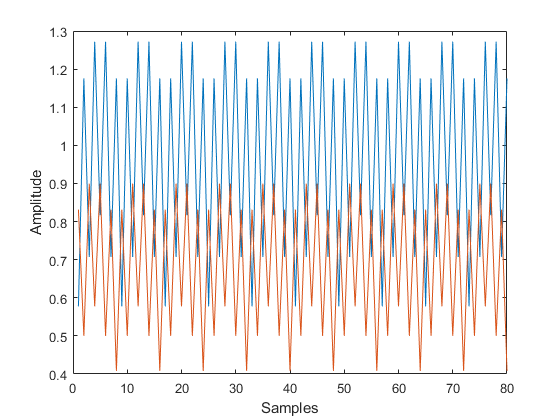

% k(27) = [];
ifft = zeros(64,1);
for nn = 1:64       
        yy = priorIFFT .* exp(j*2*pi*k*nn/64);
        ifft(nn) = (1/sqrt(12)) * sum(yy) ;
end

ifft_ = [ifft(49:64);ifft];

scale = abs(ifft_)./abs(vstfOut);

plot(abs(vstfOut))
hold on
% 
plot(abs(ifft_))

xlabel('Samples')
ylabel('Amplitude')



% postIFFT = 1/sqrt(12)* ifft(priorIFFT);

